clear all; clc

% Data settings
Speed = 15;
RPM = 8;

% Aircraft Geometry
S = 0.03469846; %m^2 (1578 ft^2/65^2)
Cmac = 0.06495; %m (13.85ft/65)

% Atmospheric Conditions
rho = 1.21; %kg/m^3
DynVisc = 1.81*10^(-5); %kg/ms

% Reynolds
Re = rho*Speed*Cmac / DynVisc

Re = 6.5129e+04

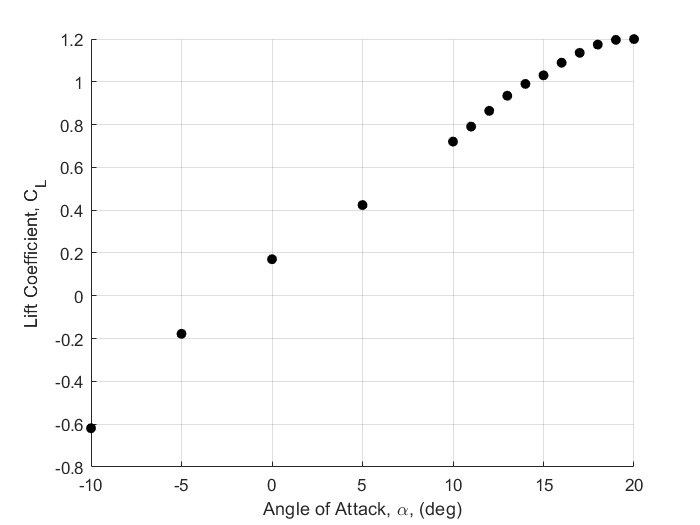


AoA = [-10, -5, 0, 5, 10:20];

for i = 1:length(AoA)

    thisAoA = AoA(i);

    % Get file names
    fileName = "u_"+ string(Speed) + "_a" + string(thisAoA) + "_r" + string(RPM)  + "_calibrated" + ".mat";
    
    x = load (fileName);
    
    % Get CL, CD, AoA
    CL(i) = (x.Fz*cosd(thisAoA) + x.Fx*sind(thisAoA)) / (0.5*rho*x.V^2*S);
    CD(i) = (x.Fz*sind(thisAoA) - x.Fx*cosd(thisAoA)) / (0.5*rho*x.V^2*S);
    Cm(i) = x.Ty / (0.5*rho*x.V^2*S*Cmac);
    
    clear x;
end

% L/D max
LDMax = 0;

for i = 1:length(AoA)    
   if CL(i)/CD(i)>LDMax
       LDMax = CL(i)/CD(i);
   end
end

% Lift Curve graph
figure
scatter(AoA,CL, 'filled','black')
xlabel('Angle of Attack, \alpha, (deg)')
ylabel('Lift Coefficient, C_{L}')
grid on


% From visual inspection,
CLa = 0.061

CLa = 0.0610

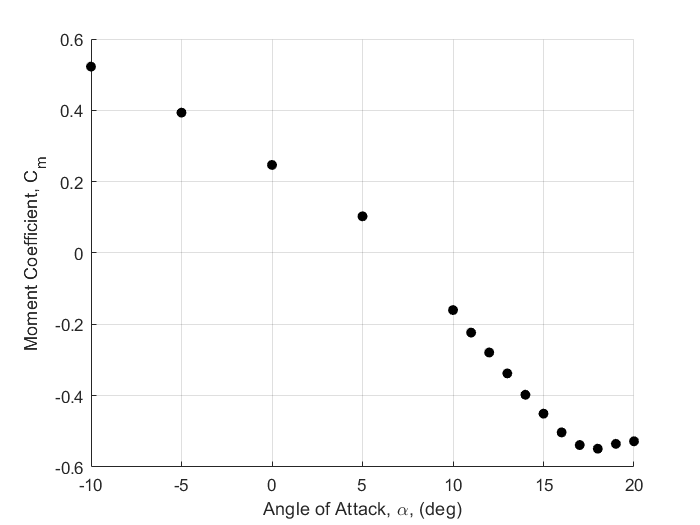


% Moment Curve graph
figure
scatter(AoA,Cm, 'filled','black')
xlabel('Angle of Attack, \alpha, (deg)')
ylabel('Moment Coefficient, C_{m}')
grid on


% From visual inspection,
Cma = -0.041

Cma = -0.0410

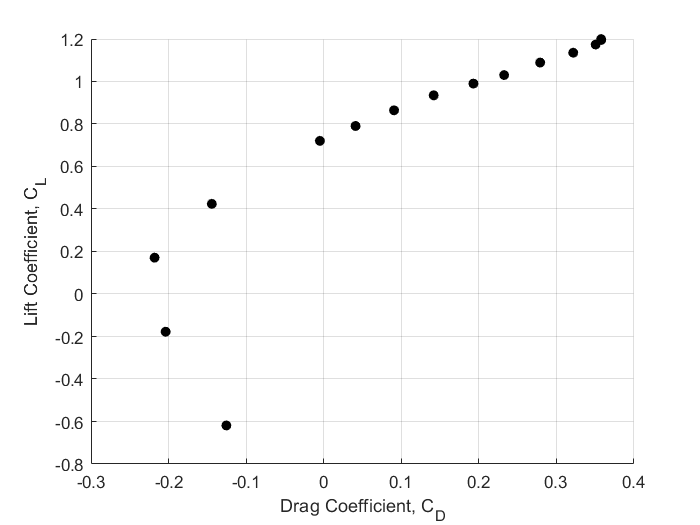


% Drag Polar
figure
scatter(CD,CL,'filled','black')
xlabel('Drag Coefficient, C_{D}')
ylabel('Lift Coefficient, C_{L}')
grid on


LDMax

LDMax = 19.2528